# Exercise 5

#### (1)  detectSURFFeatures MATLAB function 

The MATLAB function `detectSURFFeatures` is used to detect SURF (Speeded-Up Robust Features)  in an image. 

these are useful features for many tasks like object recognition and image matching.  

- Name-Value pair arguments: The function allows optional parameters which enables control over various aspects of the feature detection. 

- optional parameters: 

- `MetricThreshold`: Threshold for strongest features. Lower value will increase blobs. default: 1000

- `NumOctaves`: Octaves count as integer ≥ 1. Increase to detect larger blobs, 1-4 are the recommended values. default:3

- `NumScaleLevels`: number of scale levels for the SURF features.

- `ROI`: Region of interest as [x y width height] vector. lets us detects blobs within only a specific area. default: the whole image

`(2)`

`extractFeatures`: Extracts descriptors and their locations from image points, supporting tasks like recognition and tracking by converting image areas into processable vectors.

`points` argument should come from some other feature detection algorithm (e.g., SIFT, SURF, corners detection), marking special points in an image for more analysis such as matching or tracking.

#### (3) Read the images ’mona_org.jpg’ 

and convert it to grayscale normalized

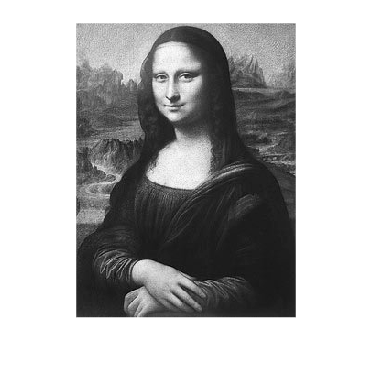

mona_org = imread_normalized('mona_org.jpg');
imshow(mona_org)

#### (4) Find all the features in the image

tic;
points = detectSURFFeatures(mona_org)

points =   111×1 SURFPoints array with properties:

              Scale: [111×1 single]
    SignOfLaplacian: [111×1 int8]
        Orientation: [111×1 single]
           Location: [111×2 single]
             Metric: [111×1 single]
              Count: 111


toc;

Elapsed time is 1.182759 seconds.


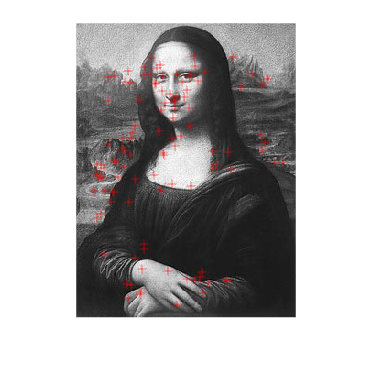


imshow(mona_org); hold on;
% Plot 'x' marks on each detected point
plot(points.Location(:,1), points.Location(:,2), 'r+');
hold off;


size(points)

ans =    111     1


it seems that we found as much as 111 features in the image=, from trees to facial features. the runtime we got for the operation may seem low, and indeed is for this type of data processing, but it might be heavy on certain real-time and computationally limited systems. (takes approximately 2 frames in 30fps which is a standard framerate)

#### (5) Find features in the image

using the pair ’ROI’, [59, 5, 128, 120].

tic;
pointsROI = detectSURFFeatures(mona_org,'ROI',[59, 5, 128, 120])

pointsROI =   26×1 SURFPoints array with properties:

              Scale: [26×1 single]
    SignOfLaplacian: [26×1 int8]
        Orientation: [26×1 single]
           Location: [26×2 single]
             Metric: [26×1 single]
              Count: 26


toc;

Elapsed time is 0.075967 seconds.



imshow(mona_org); hold on;

Unrecognized function or variable 'mona_org'.

% Plot 'x' marks on each detected point
plot(pointsROI.Location(:,1), pointsROI.Location(:,2), 'r+');
rectangle("Position",[59, 5, 128, 120])
hold off;

%size(pointsROI)
0.069 / 0.028

we presented the selected region of interest together with the feature points, the region is the face of the mona lisa. 

we see the algorithm returned a veriety of segnificant facial features, eyes, nose chin, and more. with the runtime this time we achieved a speedup of nearly 2.5! we found only 26 features this time. this is a tradeoff between realtime computational speed and sizse of detection region. as we agree to lose information about wider regions, we benefit in runtime.

# 1.2 Make Mona Straight Again

#### (1) Read the images

let's read the images ’straight_mona.PNG’ and ’crooked_mona.jpg’.

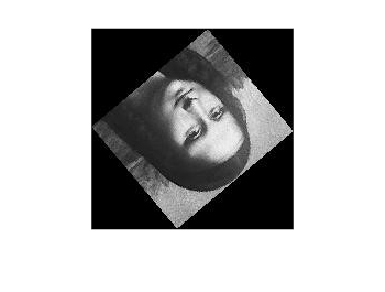

straight_mona= imread_normalized("straight_mona\straight_mona.PNG");
crooked_mona = imread_normalized("straight_mona\crooked_mona.jpg");

crooked_mona = flipud(crooked_mona);

imshow(crooked_mona)

#### (2)Extract the SURF feature points

straight_points = detectSURFFeatures(straight_mona);
crooked_points = detectSURFFeatures(crooked_mona);



#### (3) fix the mona lisa

get the locations of the features


straight_points = detectSURFFeatures(straight_mona,'MetricThreshold',200).selectStrongest(10);
crooked_points = detectSURFFeatures(crooked_mona,'MetricThreshold',200).selectStrongest(10);

% Extract features around each of the detected points
[straight_features, straight_validPoints] = extractFeatures(straight_mona, straight_points);
[crooked_features, crooked_validPoints] = extractFeatures(crooked_mona, crooked_points);


match between each feature in each picture

% Match the features based on their descriptors
indexPairs = matchFeatures(straight_features, crooked_features,'MatchThreshold',50);

% get locations of the matched points
matchedPtsStraight = straight_validPoints(indexPairs(:, 1));
matchedPtsCrooked = crooked_validPoints(indexPairs(:, 2));

let's see the locations of the featuers we extracted.

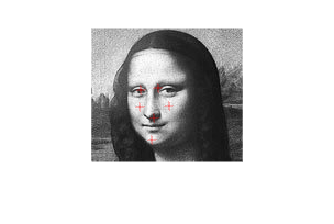

% Display straight image with matched points marked
figure; imshow(straight_mona); hold on;
plot(matchedPtsStraight.Location(:,1), matchedPtsStraight.Location(:,2), 'r+');
hold off;

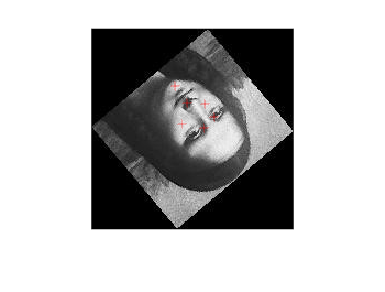


% plot 
figure; imshow(crooked_mona); hold on;
plot(matchedPtsCrooked.Location(:,1), matchedPtsCrooked.Location(:,2), 'r+');
hold off;

let's display the pairs we got

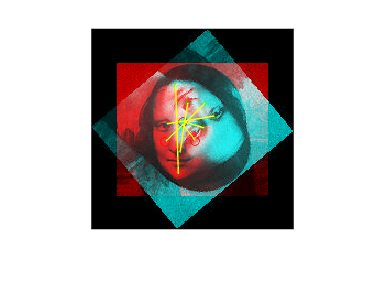

showMatchedFeatures(straight_mona,crooked_mona,matchedPtsStraight,matchedPtsCrooked)

now, based on the matches, we can build the transform, and apply it to recover the mona lisa

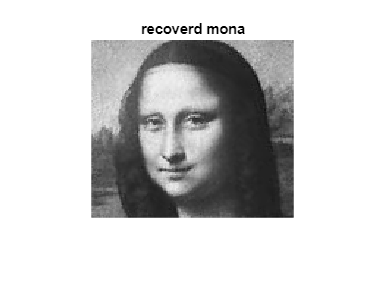

[tform,inlierIdx] = estgeotform2d(matchedPtsCrooked,matchedPtsStraight,"similarity");
outputsize = imref2d(size(straight_mona));
recoverd_mona = imwarp(crooked_mona, tform, "OutputView", outputsize);

imshow(recoverd_mona);title("recoverd mona")